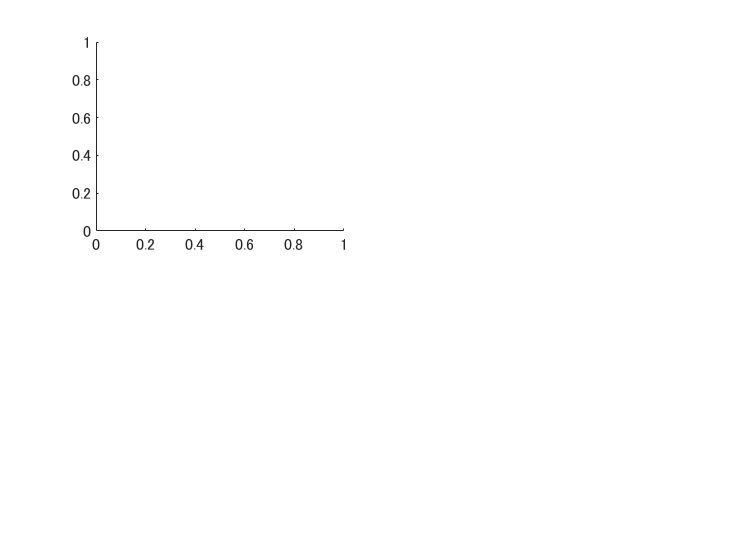

rms_Vcoil_raw =0.11369


rms_Vcoil_smoothed =0.1136


rms_fft_Vcoil_peak =0.11355


rms_fft_Ri_peak =0.1156


frequency =19998.0002


NS =3758.4939 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0901.CSV


rms_Vcoil_raw =0.19083


rms_Vcoil_smoothed =0.1907


rms_fft_Vcoil_peak =0.19064


rms_fft_Ri_peak =0.19582


frequency =19998.0002


NS =3725.0244 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0902.CSV


rms_Vcoil_raw =0.19151


rms_Vcoil_smoothed =0.19142


rms_fft_Vcoil_peak =0.19133


rms_fft_Ri_peak =0.19635


frequency =19998.0002


NS =3728.357 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0903.CSV


rms_Vcoil_raw =0.19163


rms_Vcoil_smoothed =0.19149


rms_fft_Vcoil_peak =0.19144


rms_fft_Ri_peak =0.19408


frequency =19998.0002


NS =3774.2715 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0904.CSV


rms_Vcoil_raw =0.19062


rms_Vcoil_smoothed =0.19055


rms_fft_Vcoil_peak =0.19041


rms_fft_Ri_peak =0.1941


frequency =19998.0002


NS =3753.5329 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0905.CSV


rms_Vcoil_raw =0.19122


rms_Vcoil_smoothed =0.19111


rms_fft_Vcoil_peak =0.19102


rms_fft_Ri_peak =0.19209


frequency =19998.0002


NS =3804.9026 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0906.CSV


rms_Vcoil_raw =0.19036


rms_Vcoil_smoothed =0.19031


rms_fft_Vcoil_peak =0.19006


rms_fft_Ri_peak =0.1908


frequency =19998.0002


NS =3811.3568 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0907.CSV


rms_Vcoil_raw =0.19089


rms_Vcoil_smoothed =0.19077


rms_fft_Vcoil_peak =0.19065


rms_fft_Ri_peak =0.19721


frequency =19998.0002


NS =3698.9478 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0908.CSV


rms_Vcoil_raw =0.19117


rms_Vcoil_smoothed =0.19111


rms_fft_Vcoil_peak =0.19096


rms_fft_Ri_peak =0.19037


frequency =19998.0002


NS =3838.0412 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0909.CSV


rms_Vcoil_raw =0.1912


rms_Vcoil_smoothed =0.19109


rms_fft_Vcoil_peak =0.191


rms_fft_Ri_peak =0.19565


frequency =19998.0002


NS =3735.3108 mm^2


C:\Users\yusuke\OneDrive - The University of Tokyo\WAVE\9\BZ--0910.CSV


clear all
filenames = cell(1, 10);
for i = 1:10
    filenames{i} = sprintf('C:\\Users\\yusuke\\OneDrive - The University of Tokyo\\WAVE\\9\\BZ--%04d.CSV', 900 + i);
end

for file = filenames
 M = readmatrix( file{1} );

scaling = 50; % scaling of data
Fs = 1.00E09; % sampling frequency
t = 0:1/Fs:5.00E-04; % time series
v_coil_raw = M(:,2);
v_i_raw = M(:,1);
v_coil_raw = v_coil_raw(1:scaling:end);
v_i_raw = v_i_raw(1:scaling:end);
t = t(1:scaling:end);
Fs = Fs/scaling;
len_freq = length(t);

% smoothing and filtering
perc = 0.02; % span used in smoothing
windowSize = 5; % window size in filtering
b = (1/windowSize)*ones(1,windowSize);
a = 1;
smoothed = smooth(v_coil_raw,perc,'rloess');
filtered_and_smoothed = filter(b,a,smoothed);

% fft
y_fft = fft(v_coil_raw);
P2 = abs(y_fft/len_freq);
P1 = P2(1:(len_freq-1)/2+1);
P1(2:end-1) = 2*P1(2:end-1);

y_fft_Ri = fft(v_i_raw);
P2_Ri = abs(y_fft_Ri/len_freq);
P1_Ri = P2_Ri(1:(len_freq-1)/2+1);
P1_Ri(2:end-1) = 2*P1_Ri(2:end-1);

f = Fs*(0:floor(len_freq/2))/len_freq;

% plotting
figure
subplot(2,2,1)
hold on
plot(t,filtered_and_smoothed,'LineWidth',1);
scatter(t,v_coil_raw,1);
xlabel("Time (t)")
ylabel("Coil signal (V)")
hold off
subplot(2,2,2)
scatter(t,v_i_raw,1);
xlabel("Time (t)")
ylabel("R_i signal (V)")
subplot(2,2,3)
plot(f(1:min(100,length(f))),P1(1:min(100,length(P1))))
xlabel("f (Hz)")
ylabel("Amplitude (V)")
subplot(2,2,4)
plot(f(1:min(100,length(f))),P1_Ri(1:min(100,length(P1_Ri))))
xlabel("f (Hz)")
ylabel("Amplitude (V)")

% calculate rms and peak
rms_raw = rms(v_coil_raw);
rms_smoothed = rms(filtered_and_smoothed);
[max_vcoil, i_of_max_vcoil] = max(P1);
[max_vri, i_of_max_vri] = max(P1_Ri);
helmholtz_const = 2.08001E-05;
B_rms = max_vri*10/0.1/sqrt(2)*helmholtz_const;
NS = (max_vcoil/sqrt(2)*10^6)/(2*pi*f(i_of_max_vri)*B_rms);

disp(strcat('rms_Vcoil_raw = ', num2str(rms_raw)));
disp(strcat('rms_Vcoil_smoothed = ', num2str(rms_smoothed)));
disp(strcat('rms_fft_Vcoil_peak = ', num2str(max_vcoil/sqrt(2))));
disp(strcat('rms_fft_Ri_peak = ', num2str(max_vri/sqrt(2))));
disp(strcat('frequency = ', num2str(f(i_of_max_vri))));
disp(strcat('NS = ', num2str(NS),' mm^2'));
disp(string(file));
end